# **Installation**

## **Introduction **

**Introduction**

This module demonstrates how to detect objects in images using the deep learning network **You Only Look Once version 8 (YOLOv8)**.

The computer vision content is divided into five lessons:

- **Installation: **In this lesson, you will install all the necessary tools and libraries to work with computer vision in MATLAB.

- **Training Models using Transfer Learning: **This lesson covers the basics of training a YOLO model and explains how transfer learning can improve performance and reduce training time.

- **Post-processing: **This lesson presents post-processing techniques that enhance model performance after training, including filtering and refinement of detections.

- **Evaluation: **This lesson focuses on the evaluation of object detection models using standard metrics and visualization techniques. It covers the computation of these metrics and provides guidelines for their proper interpretation.

- **Experimentation: **This final lesson provides a deeper exploration of model training. It introduces key hyperparameters, demonstrates the application of data augmentation techniques, and explains how to design experiments to evaluate different training configurations.

**Required Toolboxes**

To run this project or lesson, the following toolboxes are required:

- **Computer Vision Toolbox™**

- **Deep Learning Toolbox™**

- **Parallel Computing Toolbox™**

** Check Toolbox Installation in MATLAB**

You can use the code below to automatically check if all required toolboxes are installed:

% List of required toolboxes
requiredToolboxes = [
    "Computer Vision Toolbox"
    "Deep Learning Toolbox"
    "Parallel Computing Toolbox"
];

% Get installed toolboxes and convert names to string array
toolboxTable = matlab.addons.installedAddons;
installedNames = string(toolboxTable.Name);

% Check for missing toolboxes
missing = ~ismember(requiredToolboxes, installedNames);

% Report
if any(missing)
    missingList = requiredToolboxes(missing);
    error("Missing required toolboxes:\n%s\n\nPlease install them via Home > Add-Ons > Get Add-Ons.", ...
        strjoin(missingList, newline));
else
    disp("✅ All required toolboxes are installed.");
end

✅ All required toolboxes are installed.


**How to Install Missing Toolboxes**

If any toolbox is missing:

- Go to the **Home** tab in MATLAB.

- Click on **Add-Ons > Get Add-Ons**.

- Search for the missing toolbox by name.

- Click **Install**.

## Setup Instructions

**Add Help Module Path**

Add the path to the help module so that MATLAB can access the scripts in this folder:

addpath('help-module');

**Install Python and Required Libraries**

Use the following command to install Python and the necessary libraries. This may take more than 5 minutes:

yolo.installUltralytics();

After execute this code, it should appear a *win64* in case you are using windows, else *glnxa64*.

## Download the Dataset

To download the dataset: 

(It is not updated, is other dataset, don't download this)

%disp("download data")
%yolo.helper.downloadMultiClassData()

## Testing YOLO Is Working

Load the YOLOv8 Object Detector and Run Inference:

% Load YOLO v8 model
det = yolov8ObjectDetector2('yolov8s');

download data


% Read test image.

I = imread(fullfile('datasets/fruits_3_4998/example','orange.jpg'));

% Load YOLO v8 small network.
det = yolov8ObjectDetector2('yolov8s');

% Perform detection using pretrained model.

Pretrained yolov8s network already exists.



[bboxes, scores, labels] = detect(det, I);

% Visualize detection results.
annotations = string(labels) + ': ' + string(scores);
Iout = insertObjectAnnotation(I, 'rectangle', bboxes, annotations);
figure, imshow(Iout);

Pretrained yolov8s network already exists.



## YOLO Settings

**Set Python Environment**

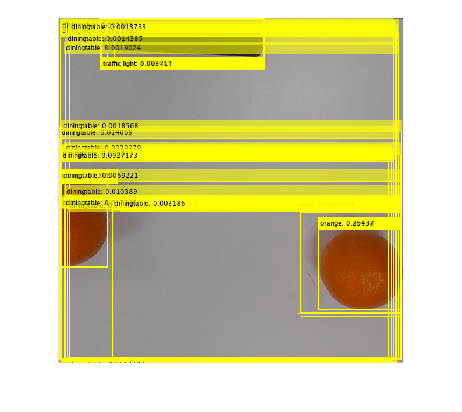

if (ispc)
    pyenv(Version="win64/python/python.exe", ExecutionMode = "OutOfProcess")
else
    pyenv(Version="glnxa64/python/bin/python3", ExecutionMode = "OutOfProcess")
end


if isunix
    py.sys.setdlopenflags(int32(bitor(int64(py.os.RTLD_LAZY),int64(py.os.RTLD_DEEPBIND))));
end


**Configure YOLO Global Settings**

% setYoloSettings Set YOLO global settings via Python wrapper.
%
% setYoloSettings(pythonObject, option, value) sets the specified YOLO
% option to the given value using the Python wrapper.
py.trainYOLOv8Wrapper.setYoloSettings(py.str('tensorboard'), true);

ans =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python.exe"
          Library: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python311.dll"
             Home: "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "30028"
      ProcessName: "MATLABPyHost"



runsDir = fullfile(pwd, 'runs'); % Une el directorio actual con la carpeta 'runs'
weightsDir = fullfile(pwd, 'weights'); % Une el directorio actual con la carpeta 'runs'
datasets_dir = fullfile(pwd, 'datasets');
py.trainYOLOv8Wrapper.setYoloSettings(py.str("runs_dir"), py.str(runsDir));
py.trainYOLOv8Wrapper.setYoloSettings(py.str("weights_dir"), py.str(weightsDir));
py.trainYOLOv8Wrapper.setYoloSettings(py.str("datasets_dir"), py.str(datasets_dir));

settings_version 0.0.4
datasets_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\datasets
weights_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\weights
runs_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\runs
uuid ec83097be249f049dc01533308f726e37a20a9a11e43afb8810c32587f8ec051
sync True
api_key 
openai_api_key 
clearml True
comet True
dvc True
hub True
mlflow True
neptune True
raytune True
tensorboard True
wandb True
True


settings_version 0.0.4
datasets_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\datasets
weights_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\weights
runs_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\runs
uuid ec83097be249f049dc01533308f726e37a20a9a11e43afb8810c32587f8ec051
sync True
api_key 
openai_api_key 
clearml True
comet True
dvc True
hub True
mlflow True
neptune True
raytune True
tensorboard True
wandb True
True


settings_version 0.0.4
datasets_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\datasets
weights_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\weights
runs_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\runs
uuid ec83097be249f049dc01533308f726e37a20a9a11e43afb8810c32587f8ec051
sync True
api_key 
openai_api_key 
clearml True
comet True
dvc True
hub True
mlflow True
neptune True
raytune True
tensorboard True
wandb True
True


settings_version 0.0.4
datasets_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\datasets
weights_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\weights
runs_dir C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\runs
uuid ec83097be249f049dc01533308f726e37a20a9a11e43afb8810c32587f8ec051
sync True
api_key 
openai_api_key 
clearml True
comet True
dvc True
hub True
mlflow True
neptune True
raytune True
tensorboard True
wandb True
True
